clc;               
clear all;          
close all;
bdclose('all'); 

%%%%%%%%%%%%%%%%%%%%%%%%%% Initialisations des parametres  %%%%%%%%%%%%%%%%%%%%%%%%

%paramètres
epsilon = 0.00000001;
lambda_1 = 10;
lambda_2 = 50;
lambda_3 = 100;

% Reference 

% Temps final
tfinal = 20;

% Conditions initiales
u0 = 1.0;  v0 = 1.0; r0 = 1.0; 

% trajectoire
tmps=0:0.01:10;
t_0 = 5;
gama = 2;
vh = 3;
vl = -3;
u_r = vl + (vh-vl)*(tanh(gama*(tmps-t_0)) + 1)/2;
v_r = vl + (vh-vl)*(tanh(gama*(tmps-t_0)) + 1)/2;


%%%%%%%%%%%%%%%%%%%%%%%%%% Resolution des equations  %%%%%%%%%%%%%%%%%%%%%%%%%
disp('Simulation de sys');

Simulation de sys


relTol = 1e-4;    absTol = 1e-7;  
options = odeset('RelTol', relTol, 'AbsTol', absTol);
[ts,Xs] = ode23tb(@ (t,X) dyn(t, X,lambda_1,lambda_2,lambda_3,tmps,u_r,v_r), [0 tfinal], [u0 v0 r0],... 
     options); 

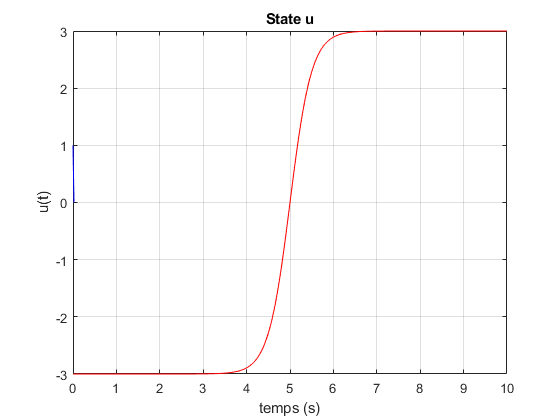


%%%%%%%%%%%%%%%%%%%%%%%%%% Extraction des etats et commades %%%%%%%%%%%%%%%%%%%%%%%%

u = Xs(:,1);  v = Xs(:,2); r = Xs(:,3); 

% u_r = interp1(tmps,u_r,t);
% v_r = interp1(tmps,v_r,t);
% du_r = 1 - (u_r)^2;
% dv_r = 1 - (v_r)^2;
% ddv_r = -2*v_r*dv_r;
% 
% % calcul des commandes
% 
% tau_u = du_r -lambda_1.*(u-u_r)- v.*r;
% tau_r = -(1./(u + epsilon)).*( ddv_r - lambda_2.*(v-v_r) - lambda_3.*(- u.*r - dv_r) + v.*(r.^2) + tau_u.*r);

%%%%%%%%%%%%%%%%%%%%%%%%%% Ploting %%%%%%%%%%%%%%%%%%%%%%%%
% control u
figure(1);
plot(ts,u,'b',tmps,u_r,'r'); grid on; 
xlabel('temps (s)'); ylabel('u(t)');    
title('State u');

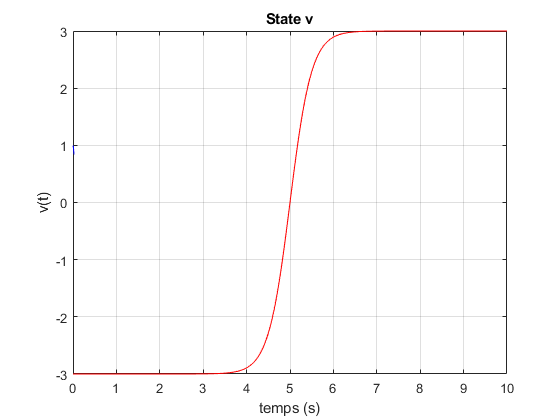


% speed v
figure(2);
plot(ts,v,'b',tmps,v_r,'r'); grid on; 
xlabel('temps (s)'); ylabel('v(t)');    
title('State v');

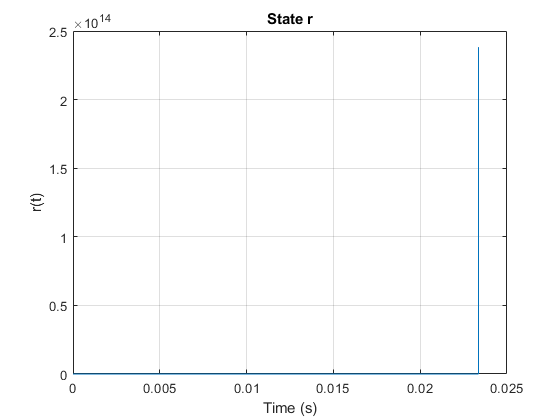


% speed r
figure(3);
plot(ts,r); grid on; 
xlabel('Time (s)'); ylabel('r(t)');    
title('State r');


% % commandes tau_u
% figure(4);
% plot(ts, tau_u); grid; 
% xlabel('Time (s)'); ylabel('T_u');
% title('control T_u');
% 
% %commandes tau_r
% figure(5);
% plot(ts, tau_r); grid; 
% xlabel('Time (s)'); ylabel('T_r');
% title('control T_r');


function [dotX] = dyn(t, X, lambda_1,lambda_2,lambda_3,tmps,u_r,v_r)


  % récuperation des variables d'etat
  u = X(1,:);  v = X(2,:); r = X(3,:);
  epsilon = 0.00000001;
  
  u_r = interp1(tmps,u_r,t);
  v_r = interp1(tmps,v_r,t);
  du_r = 1 - (u_r)^2;
  dv_r = 1 - (v_r)^2;
  ddv_r = -2*v_r*dv_r;

  % calcul des commandes
  tau_u = du_r -lambda_1.*(u-u_r)- v.*r;
  tau_r = -(1./(u + epsilon)).*( ddv_r - lambda_2.*(v-v_r) - lambda_3.*(- u.*r - dv_r) + v.*(r.^2) + tau_u.*r);

  % equations du systeme

  dotu = v.*r + tau_u;
  dotv = -u.*r;
  dotr = tau_r;

  % renvoi d'arguments 
  dotX = [dotu dotv dotr]';
end 
